# Optimal Threshold of SVD Recomposition

*Author: Koby Taswell*

First load our file and let's add some noise with the Gaussian Patter

path = 'Kingfisher.jpg';

I = imread(path);

n = max(size(I))

n = 1724

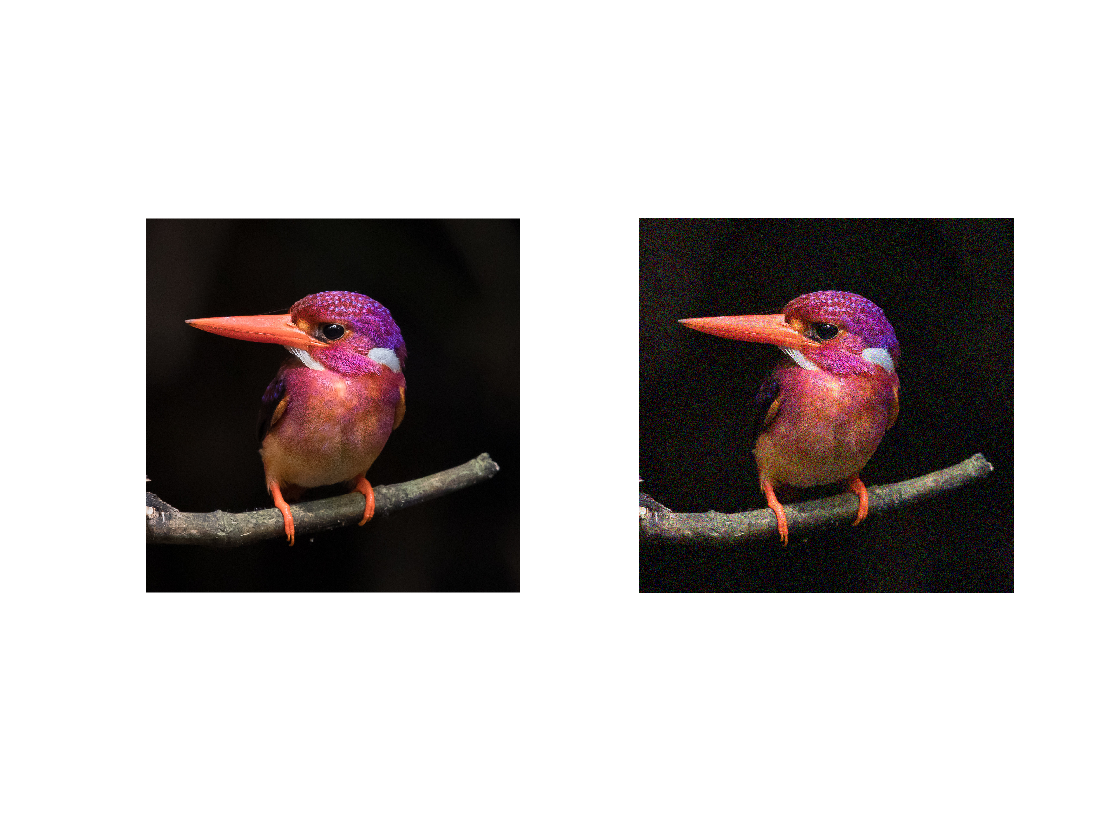


Inoisey = imnoise(I, "gaussian");

subplot(1,2,1)
imshow(I);

subplot(1,2,2)
imshow(Inoisey)

ImseUint = immse(I, Inoisey)

ImseUint = 429.7998


I = im2double(I);
Inoisey = im2double(Inoisey);

ImseDoubleNoisey = immse(I, Inoisey)

ImseDoubleNoisey = 0.0066

We see that the image is fairly noisey. Though it seems like it is higher when the data is not in double precision. So perhaps MSE is not appropriate here...

Next we calculate the SVD of each color channel RGB,

[UnoiseyR, SnoiseyR, VnoiseyR] = svd(Inoisey(:, :, 1)); % Red Channel
[UnoiseyG, SnoiseyG, VnoiseyG] = svd(Inoisey(:, :, 2)); % Green Channel
[UnoiseyB, SnoiseyB, VnoiseyB] = svd(Inoisey(:, :, 3)); % Blue Channel

Now we need to find the threshold which will let us find the rank of our approximation.

As defined in Gavish & Donoho 2014, we can find the threshold of an arbitrary n by n matrix as approximately tau = 2.858*median(S)

First find medians of each color channel:

sMedR = median(diag(SnoiseyR)) % Red single values

sMedR = 2.8473

sMedG = median(diag(SnoiseyG)) % Green single values

sMedG = 2.7270

sMedB = median(diag(SnoiseyB)) % Blue single values

sMedB = 2.6734


c = 2.858 % threshold coefficeint

c = 2.8580


tRed = c*sMedR

tRed = 8.1377

tGre = c*sMedG

tGre = 7.7937

tBlu = c*sMedB

tBlu = 7.6406

Set singular values below threshold to zero in each channel

SdenoiseR = SnoiseyR;
SdenoiseG = SnoiseyG;
SdenoiseB = SnoiseyB;

SdenoiseR(SdenoiseR < tRed) = 0;
SdenoiseG(SdenoiseG < tGre) = 0;
SdenoiseB(SdenoiseB < tBlu) = 0;

Reconstruct each matrix

DenoisedRed = UnoiseyR*SdenoiseR*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseG*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseB*VnoiseyB.';

Idenoised = cat(3, DenoisedRed, DenoisedGre, DenoisedBlu);

Display for Visual Assessment

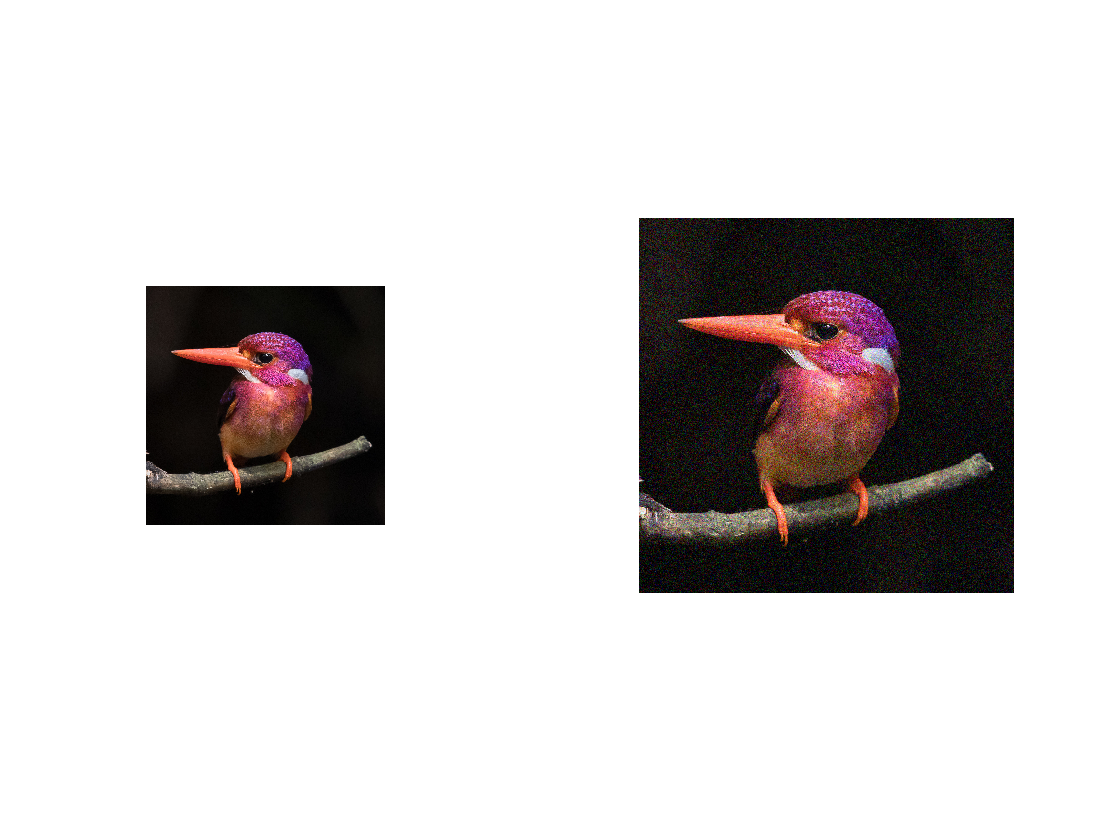

subplot(1,3,1)
imshow(I);

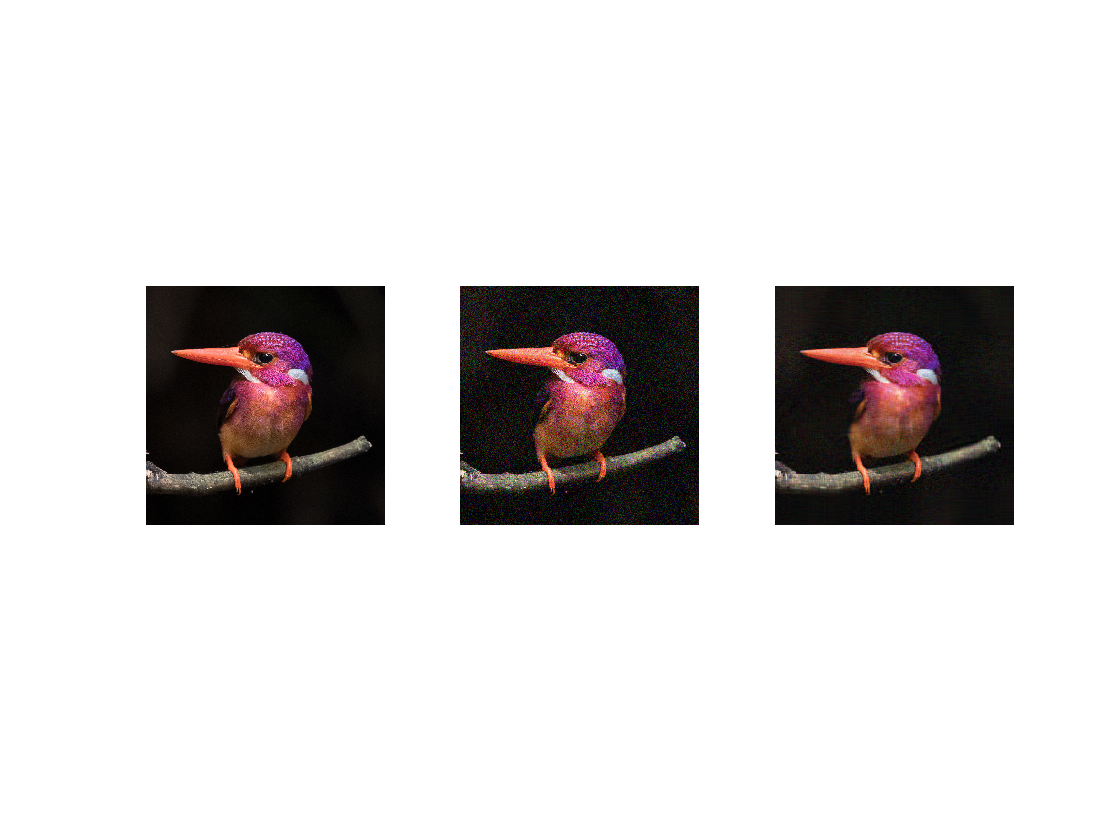


subplot(1,3,2)
imshow(Inoisey);

subplot(1,3,3)
imshow(Idenoised)

And calculate new MSE

ImseDoubleDenoise = immse(I, Idenoised)

ImseDoubleDenoise = 0.0022

Another method of measuring the perfromance of the matrix reconstruction is to caclulate the Frobenius Distance between the two signals (Shablin and Nobel). 

RedDistance = norm(I(:, :, 1)-Idenoised(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-Idenoised(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-Idenoised(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 79.9746

Test to see if denoised image MSE is smaller than noisey image MSE

testMse = ImseDoubleDenoise < ImseDoubleNoisey

testMse = logical
   1


Let's test to see if we can use the direct estimation via known values of noise for our square matrix

Assuming this is an accurate measurement of signal-noise-ratio

noiseRed = immse(I(:, :, 1), Inoisey(:, :, 1));
noiseGre = immse(I(:, :, 2), Inoisey(:, :, 2));
noiseBlu = immse(I(:, :, 3), Inoisey(:, :, 3));

d = (4/sqrt(3));

tRedSq = d*sqrt(n)*noiseRed;
tGreSq = d*sqrt(n)*noiseGre;
tBluSq = d*sqrt(n)*noiseBlu;

Now apply our new thresholds

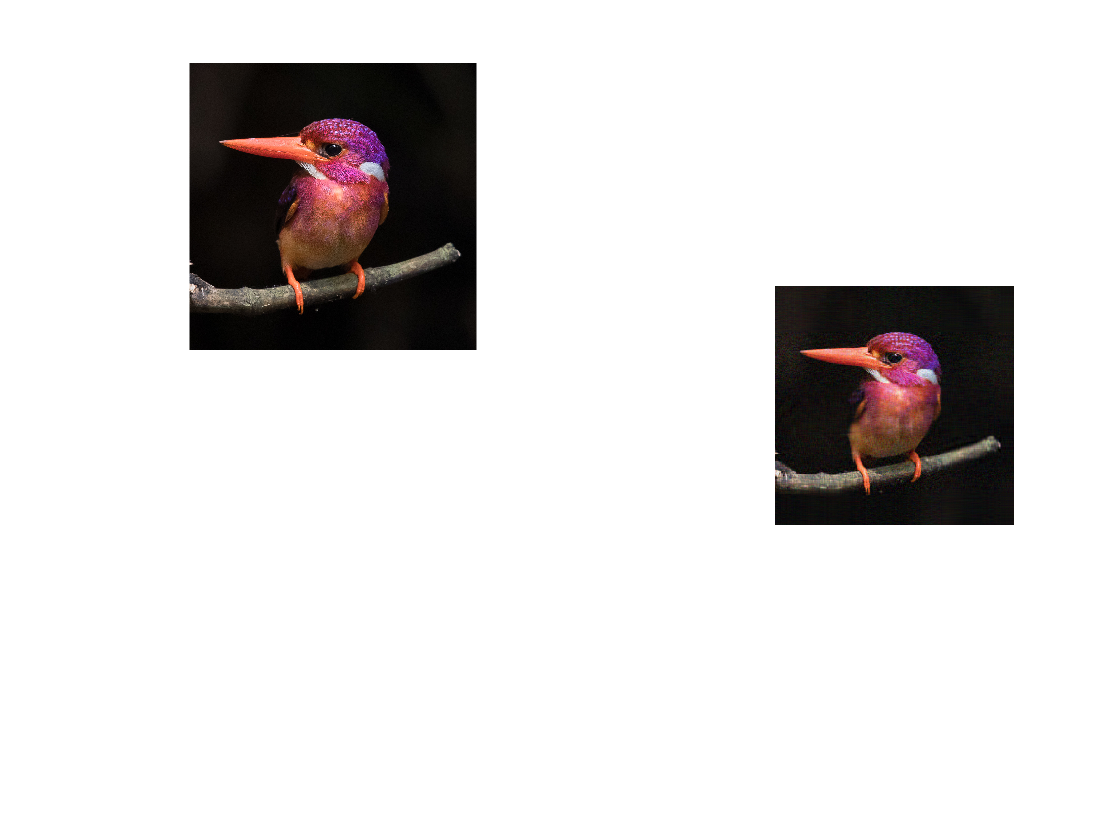

SdenoiseRsq = SnoiseyR;
SdenoiseGsq = SnoiseyG;
SdenoiseBsq = SnoiseyB;

SdenoiseRsq(SdenoiseRsq < tRedSq) = 0;
SdenoiseGsq(SdenoiseGsq < tGreSq) = 0;
SdenoiseBsq(SdenoiseBsq < tBluSq) = 0;

DenoisedRed = UnoiseyR*SdenoiseRsq*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseGsq*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseBsq*VnoiseyB.';

IdenoiseSq = cat(3, DenoisedRed,DenoisedGre, DenoisedBlu);

subplot(2,2,1)
imshow(I);

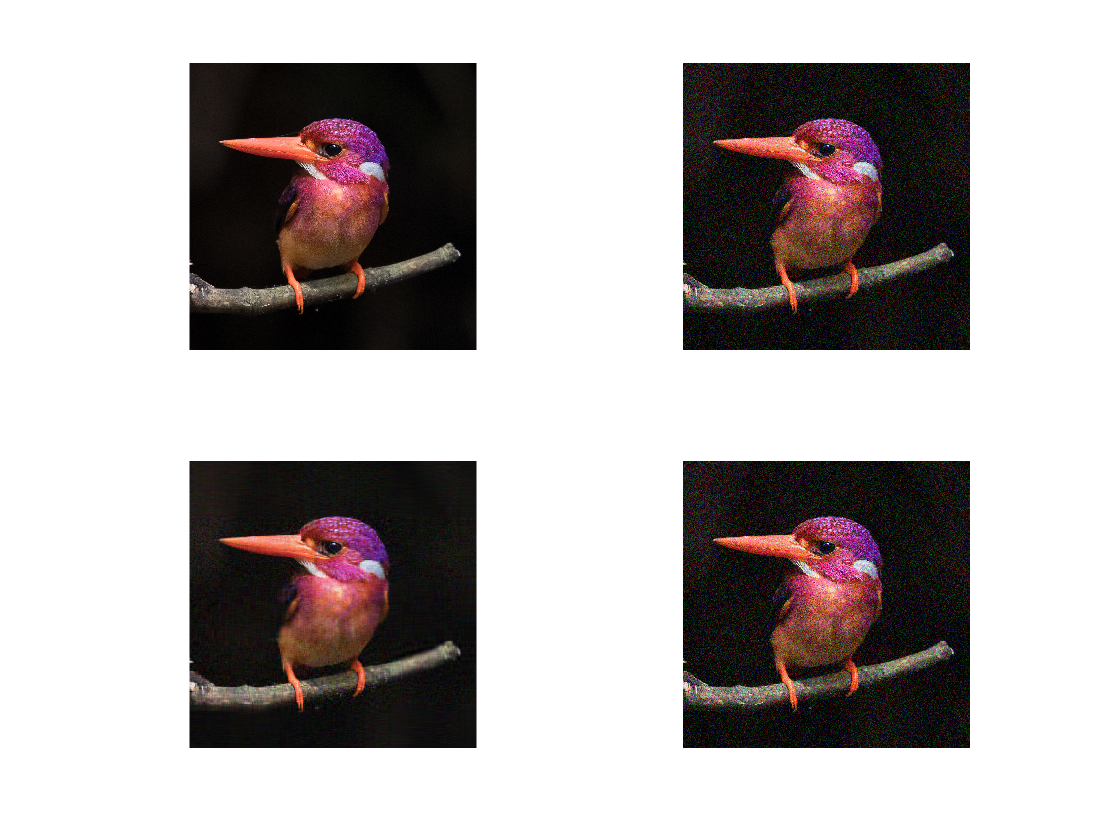


subplot(2,2,2)
imshow(Inoisey);

subplot(2,2,3)
imshow(Idenoised);

subplot(2,2,4)
imshow(IdenoiseSq)

ImseDoubleDenoiseSq = immse(I, IdenoiseSq)

ImseDoubleDenoiseSq = 0.0066

Now lets calculate the Frobenius distance. . 

RedDistance = norm(I(:, :, 1)-IdenoiseSq(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-IdenoiseSq(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-IdenoiseSq(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 140.0655

We can see that the hard thresholding for arbitrary noise performs better than the direct estimation with known noise.  

Finally lets see how Bulk Edge thresholding performs.

Recall our existing Signal-noise-ratios for each color channel:

disp(noiseRed)

    0.0068



disp(noiseGre)

    0.0066



disp(noiseBlu)

    0.0064



Get beta where beta = m/n

[m,n,dim] = size(I);
beta = m/n

beta = 1

According to Gavish & Donoho 2014, the distribution of singular values will form a quarter circle bulk which lies at (1+sqrt(beta) * sqrt(n) * noise 

t = 1+sqrt(beta)

t = 2

tRedBulk = t*sqrt(n)*noiseRed;
tGreBulk = t*sqrt(n)*noiseGre;
tBluBulk = t*sqrt(n)*noiseBlu;

apply thresholds and reconstruct

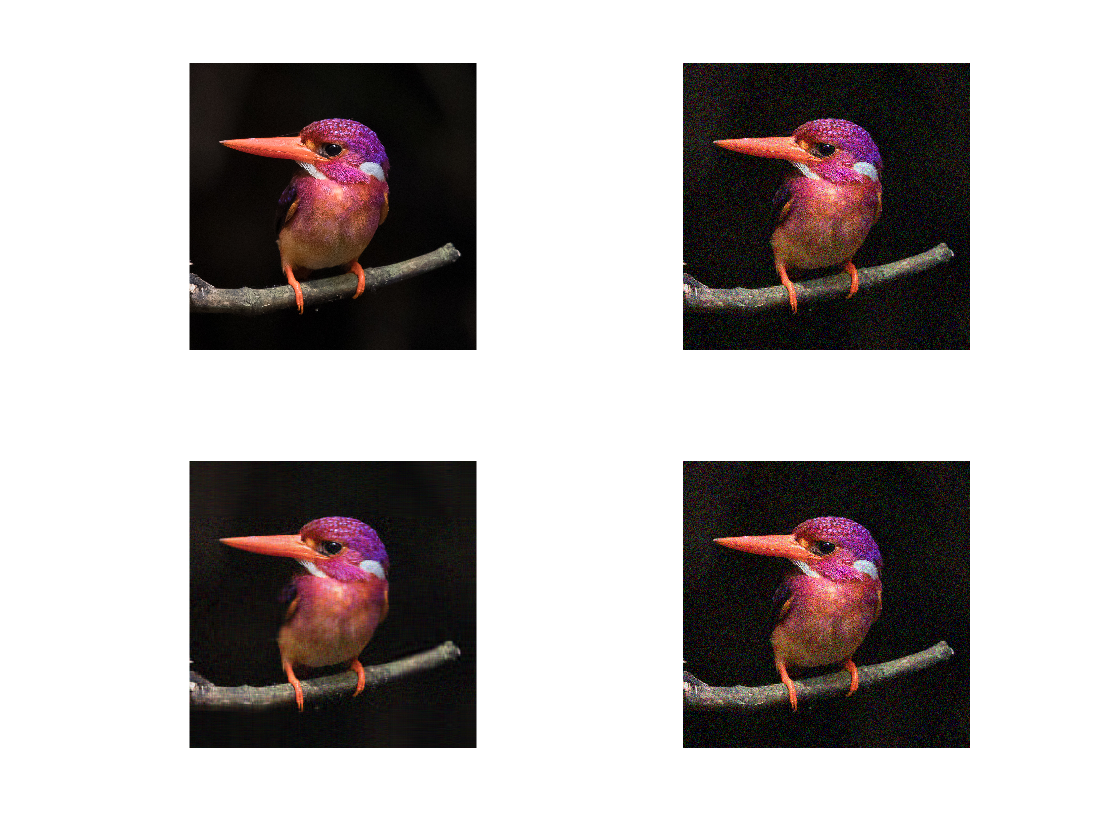

SdenoiseRbulk = SnoiseyR;
SdenoiseGbulk = SnoiseyG;
SdenoiseBbulk = SnoiseyB;


SdenoiseRbulk(SdenoiseRbulk < tRedBulk) = 0;
SdenoiseGbulk(SdenoiseGbulk < tGreBulk) = 0;
SdenoiseBbulk(SdenoiseBbulk < tBluBulk) = 0;

DenoisedRed = UnoiseyR*SdenoiseRbulk*VnoiseyR.';
DenoisedGre = UnoiseyG*SdenoiseGbulk*VnoiseyG.';
DenoisedBlu = UnoiseyB*SdenoiseBbulk*VnoiseyB.';

IdenoiseBulk = cat(3, DenoisedRed,DenoisedGre, DenoisedBlu);

subplot(2,2,1)
imshow(I);

subplot(2,2,2)
imshow(Inoisey);

subplot(2,2,3)
imshow(Idenoised);

subplot(2,2,4)
imshow(IdenoiseBulk)

Calculate MSE

ImseDoubleDenoiseBulk = immse(I, IdenoiseBulk)

ImseDoubleDenoiseBulk = 0.0066

RedDistance = norm(I(:, :, 1)-IdenoiseBulk(:, :, 1),'fro');
BluDistance = norm(I(:, :, 2)-IdenoiseBulk(:, :, 2),'fro');
GreDistance = norm(I(:, :, 3)-IdenoiseBulk(:, :, 3),'fro');
FroDistance = (RedDistance + BluDistance + GreDistance) / 3

FroDistance = 140.0960

We see that bulk edge thresholding performs just as well as the square matrix estimation with known noise described in Gavish & Donoho 2014.

To investigate this, let's take a look at the number of singular values each of the square matrix estimation and bulk edge thresholding remove.

sRed = diag(SnoiseyR);
sGre = diag(SnoiseyG);
sBlu = diag(SnoiseyB);

sRemovedR = sum(sRed < tRed);
sRemovedG = sum(sGre < tGre);
sRemovedB = sum(sBlu < tBlu);
sRemovedSqR = sum(sRed < tRedSq);
sRemovedSqG = sum(sGre < tGreSq);
sRemovedSqB = sum(sBlu < tBluSq);
sRemovedBulkR = sum(sRed < tRedBulk);
sRemovedBulkG = sum(sGre < tGreBulk);
sRemovedBulkB = sum(sBlu < tBluBulk);
sRemovedMat = [sRemovedR, sRemovedSqR, sRemovedBulkR;
            sRemovedG, sRemovedSqG, sRemovedBulkG;
            sRemovedB, sRemovedSqG, sRemovedBulkB]

sRemovedMat =         1670         208         179
        1679         209         182
        1669         209         179


sKeptMat = n*ones(3,3) - sRemovedMat

sKeptMat =           54        1516        1545
          45        1515        1542
          55        1515        1545


It appears as if the arbitrary removal method is a much lower rank approximation as opposed to either method which utilizes a known signal to noise ratio. 